clear 
clc 
close all

## **Reading data recorded from magnetic testbed**

%%%Add data with increasing current
load('y_coil18012024.mat');
time = y_coil_data(1,:);
Bx = y_coil_data(2,:); By = y_coil_data(3,:); Bz = y_coil_data(4,:);
V  = y_coil_data(5,:); I  = y_coil_data(6,:);

ycoil.data_down.raw.time = time(~isnan(time));
ycoil.data_down.raw.Bx = Bx(~isnan(Bx)); 
ycoil.data_down.raw.By = By(~isnan(By)); 
ycoil.data_down.raw.Bz = Bz(~isnan(Bz));
ycoil.data_down.raw.V  = V(~isnan(V)); 
ycoil.data_down.raw.I  = I(~isnan(I));
%%%Interpolated data
[ycoil.data_down.int.time, ycoil.data_down.int.Bx] = setSampleTime(ycoil.data_down.raw.time,ycoil.data_down.raw.Bx,0.2);
[ycoil.data_down.int.time, ycoil.data_down.int.By] = setSampleTime(ycoil.data_down.raw.time,ycoil.data_down.raw.By,0.2);
[ycoil.data_down.int.time, ycoil.data_down.int.Bz] = setSampleTime(ycoil.data_down.raw.time,ycoil.data_down.raw.Bz,0.2);
[ycoil.data_down.int.time, ycoil.data_down.int.V] = setSampleTime(ycoil.data_down.raw.time,ycoil.data_down.raw.V,0.2);
[ycoil.data_down.int.time, ycoil.data_down.int.I] = setSampleTime(ycoil.data_down.raw.time,ycoil.data_down.raw.I,0.2);

**Check Data**

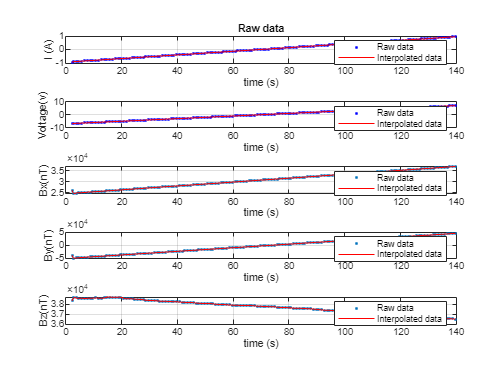

figure()
p1 = subplot(5,1,1);
    h1 = plot(ycoil.data_down.raw.time,ycoil.data_down.raw.I,'b.'); hold on;
    h2 = plot(ycoil.data_down.int.time,ycoil.data_down.int.I,'r-');
    legend([h1,h2],'Raw data','Interpolated data')
    title('Raw data'); xlabel('time (s)'); ylabel('I (A)');grid on;
p2 = subplot(5,1,2);
    h3 = plot(ycoil.data_down.raw.time,ycoil.data_down.raw.V,'b.'); hold on;
    h4 = plot(ycoil.data_down.int.time,ycoil.data_down.int.V,'r-');
    legend([h3,h4],'Raw data','Interpolated data');
    xlabel('time (s)'); ylabel('Voltage(v)');grid on;
p3 = subplot(5,1,3);
    h5 = plot(ycoil.data_down.raw.time,ycoil.data_down.raw.Bx,'.'); hold on;
    h6 = plot(ycoil.data_down.int.time,ycoil.data_down.int.Bx,'r-');
    legend([h5,h6],'Raw data','Interpolated data');
    xlabel('time (s)'); ylabel('Bx(nT)');grid on;
p4 = subplot(5,1,4);
    h7 = plot(ycoil.data_down.raw.time,ycoil.data_down.raw.By,'.'); hold on;
    h8 = plot(ycoil.data_down.int.time,ycoil.data_down.int.By,'r-');
    legend([h7,h8],'Raw data','Interpolated data');
    xlabel('time (s)'); ylabel('By(nT)');grid on;
p5 = subplot(5,1,5);
    h9  = plot(ycoil.data_down.raw.time,ycoil.data_down.raw.Bz,'.'); hold on;
    h10 = plot(ycoil.data_down.int.time,ycoil.data_down.int.Bz,'r-');
    legend([h9,h10],'Raw data','Interpolated data');
    xlabel('time (s)'); ylabel('Bz(nT)');grid on;
    linkaxes([p1,p2,p3,p4,p5],'x');

## **Setting Parameters**

### **For Z axis**

IS501NMTB.Z.L = 1.03;
IS501NMTB.Z.a = IS501NMTB.Z.L/2 ;
%IS501NMTB.Z.h = 0.5 ;
IS501NMTB.Z.h = 1.03 ;
IS501NMTB.Z.N = 59.12; 

### **For Y axis**

IS501NMTB.Y.L = 1.02;
IS501NMTB.Y.a = IS501NMTB.Y.L/2 ;
IS501NMTB.Y.h = 0.5 ;
IS501NMTB.Y.N = 111.2; 

### **For X axis**

IS501NMTB.X.L = 1.03;
IS501NMTB.X.a = IS501NMTB.X.L/2 ;
%IS501NMTB.X.h = 0.5;
IS501NMTB.X.h = 1.03;
IS501NMTB.X.N = 97.18;

## **Simulation**

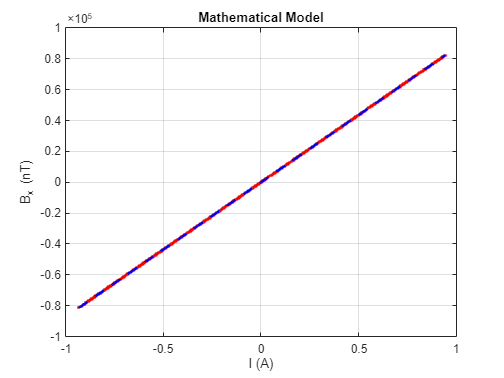

%%%Simulated data 
%%%Biot Savart law at x=0
mu_0 = 4*pi*1e-7;    % Permeability in the vacum
functBxyz0 = @(N,I,a,h) (4 * mu_0 * N *I * a^2) / (pi) * (1/((a^2 + (h/2)^2) * (2 * a^2 + (h/2)^2)^(1/2)));

%%%Start simulation at x=0
simulated.Iarr = ycoil.data_down.int.I;
simulated.B_y = functBxyz0(IS501NMTB.X.N, simulated.Iarr, IS501NMTB.X.a, IS501NMTB.X.h)*1E9; %% In (nT)
%%%Linear Regresion
%%%Perform linear regression of degree 1 (a straight line)
degree_of_polynomial = 1;
coeffs = polyfit(simulated.Iarr, simulated.B_y, degree_of_polynomial);
%%%Coeffs will contain the coefficients of the fitted polynomial (in this case, the slope and intercept)
slope = coeffs(1); intercept = coeffs(2);

x_fit = linspace(min(simulated.Iarr), max(simulated.Iarr), 50); %%% x values for the regression line
y_fit = polyval(coeffs, x_fit); % Calculate fitted y values

figure()
plot(simulated.Iarr,simulated.B_y,'r.'); hold on; grid on
plot(x_fit, y_fit, 'b--','LineWidth',2); % Linear regression line
title('Mathematical Model');
xlabel('I (A)'); ylabel('B_x (nT)');

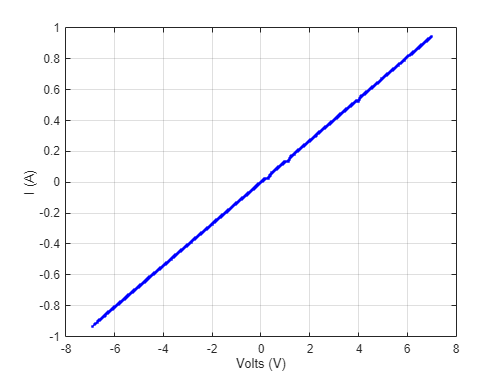

%%%Real data
figure
    plot(ycoil.data_down.int.V,ycoil.data_down.int.I,'b.'); grid on;
    xlabel('Volts (V)'); ylabel('I (A)');

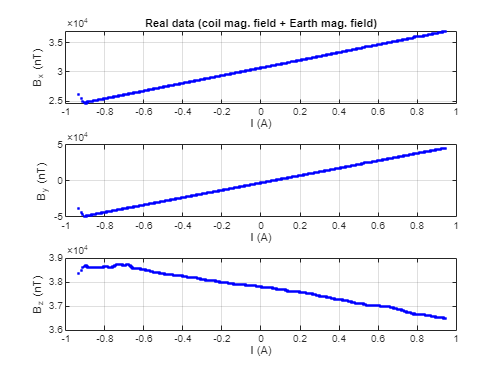

figure
subplot(3,1,1)
    plot(ycoil.data_down.int.I,ycoil.data_down.int.Bx,'b.'); grid on;
    title('Real data (coil mag. field + Earth mag. field)');
    xlabel('I (A)'); ylabel('B_x (nT)');
subplot(3,1,2)
    plot(ycoil.data_down.int.I,ycoil.data_down.int.By,'b.'); grid on;
    xlabel('I (A)'); ylabel('B_y (nT)');
subplot(3,1,3)
    plot(ycoil.data_down.int.I,ycoil.data_down.int.Bz,'b.'); grid on;
xlabel('I (A)'); ylabel('B_z (nT)');

## Real **plant** stimation

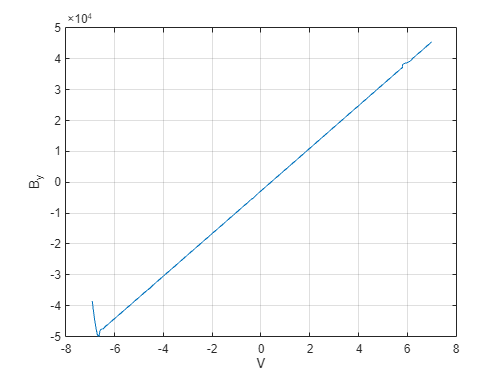

%%% Prepare data for identification
input  = ycoil.data_down.int.V';
output = ycoil.data_down.int.By';
figure()
plot(input,output); grid on; xlabel('V'); ylabel('B_y')

figure()

% Create object for time-series data
estimationData = iddata(output,input,0.2);

% Estimate process model
sys = procest(estimationData,'P2Z');

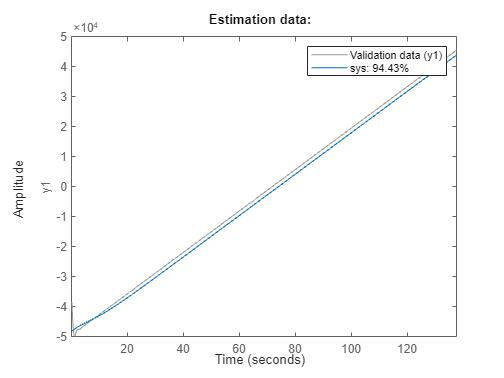


% Display results
compare(estimationData,sys);
clear estimationData;
title('Estimation data:');

sys

sys =
 
Process model with transfer function:
                   1+Tz*s            
  G(s) = Kp * ------------------     
              (1+Tp1*s)(1+Tp2*s)     
                                     
         Kp = 6900.7                 
        Tp1 = 4.5513                 
        Tp2 = 4.3827                 
         Tz = 2.7486                 
                                     
Parameterization:
    {'P2Z'}
   Number of free coefficients: 4
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                      
Estimated using PROCEST on time domain data "estimationData".
Fit to estimation data: 94.43%                               
FPE: 2.371e+06, MSE: 2.33e+06                                
 


%%turno into ss
systf = tf(sys);
[A,B,C,D] = tf2ss(systf.Numerator{1, 1}, systf.Denominator{1, 1});
disp('A:'); disp(A); disp('B:'); disp(B); disp('C:'); disp(C); disp('D:'); disp(D);

A:
   -0.4479   -0.0501
    1.0000         0

B:
     1
     0

C:
  950.8720  345.9537

D:
     0



**Controller Design**

- **Open Loop evaluation**

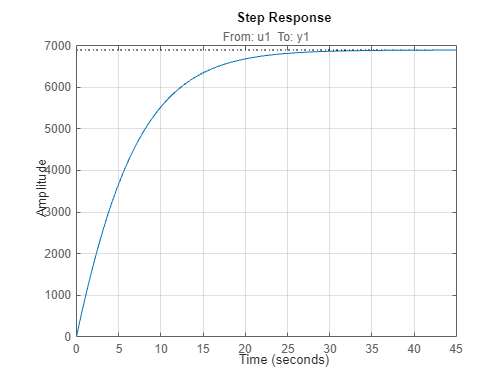

step(sys);grid on;

% Obtener información sobre la respuesta al escalón
info = stepinfo(sys)

info = struct with fields:
         RiseTime: 13.0318
    TransientTime: 22.2623
     SettlingTime: 22.2623
      SettlingMin: 6.2171e+03
      SettlingMax: 6.8999e+03
        Overshoot: 0
       Undershoot: 0
             Peak: 6.8999e+03
         PeakTime: 47.9968


- Close Loop

## PID controller

PID = pidtune(sys,'PID');
disp('kp');disp(PID.Kp); disp('kd');disp(PID.Kd); disp('ki');disp(PID.Ki);

kp
   2.2907e-04

kd
     0

ki
   6.5481e-05



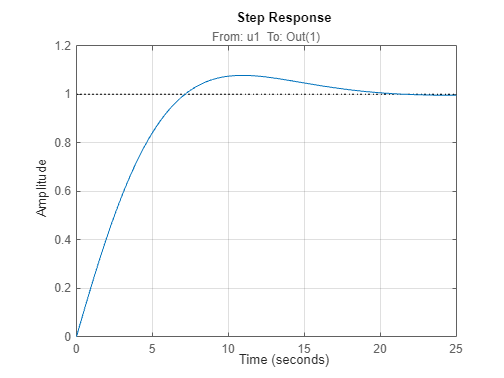

%%%close loops
closeLoop = feedback(PID*sys,1);                                    
step(closeLoop); grid on;

info = stepinfo(closeLoop)

info = struct with fields:
         RiseTime: 5.1659
    TransientTime: 17.8346
     SettlingTime: 17.8346
      SettlingMin: 0.9101
      SettlingMax: 1.0782
        Overshoot: 7.8222
       Undershoot: 0
             Peak: 1.0782
         PeakTime: 11.0368


% A = [-1.9361 -0.0176; 1 0];  
% B = [1; 0];  
% C = [1545.8 63.9];  
% D = 0;  
% geneticAlgorithm(A, B, C, D)  

- Real time simulation

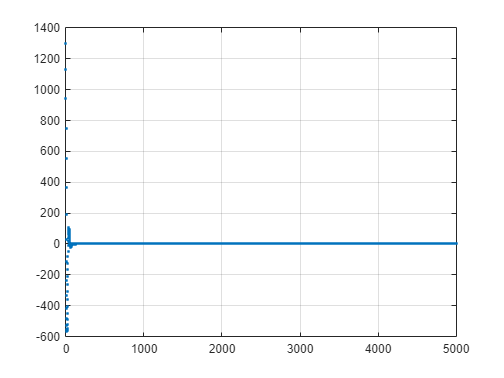

%%Simulation settings
dt        = 1; %%s
finalTime = 5000;
setpoint = 0; 

%% Progress bar
settings.hWaitbar = waitbar(0, 'Progress: 0%','Name', 'IS501 MagneticTestBed');


%%create a timevector
t = 0:dt:finalTime;

%%calculate disturbances in advance
%Tdis = disturbance(t);

%%Containers
x = zeros(2,length(t));
y = zeros(1,length(t));
u = zeros(1,length(t)); 

%%Initial conditions
x(:,1) = [1,1]';
y(1)   = C*x(:,1);
integralvalue = 0;
prev_error = 0;

%%PID gains
Kp = 9.501072011300458e-06;
Ki = 1.996463879247196e-05;
Kd = 0;

for i=1:length(t)
    %%%PID controller
    % Calculate error
    error = setpoint - y(i);
    
    % Proportional term
    P = Kp * error;
    
    % Integral term
    integralvalue = integralvalue + Ki * error * dt;
    
    % Derivative term
    derivative = Kd * (error - prev_error) / dt;
    
    % PID control law
    u(i) = P + integralvalue + derivative;
    
    
    %Empezamos en RK 4 de cuarto orden
    g1=dt*xcoilfun(t(i), x(:,i), u(i),A,B);
    g2=dt*xcoilfun(t(i), x(:,i)+0.5.*g1, u(i),A,B);
    g3=dt*xcoilfun(t(i), x(:,i)+0.5.*g2, u(i),A,B);
    g4=dt*xcoilfun(t(i), x(:,i)+0.5.*g3, u(i),A,B);
    x(:,i+1)=x(:,i)+(1/6).*(g1+2.*g2+2.*g3+g4);
    y(i+1)=C*x(:,i)+D*u(i);
    
    %%% Progress bar configuration
    %%%% Calculate the progress percentage
    progress = t(i) / finalTime;
    
    if isa(settings.hWaitbar,'handle') && isvalid(settings.hWaitbar)
        if t(i) == t(end)
            % Close the progress bar when the simulation is complete
            close(settings.hWaitbar);
        else
            % Update the progress bar
            waitbar(progress, settings.hWaitbar, sprintf('Progress: %.1f%%', progress*100));
        end
    end
prev_error = error;
end

figure()
plot(t,y(1:end-1),'.');grid on;

% % % %%%Real data - measured earth magnetic field
% % % figure
% % % subplot(3,1,1)
% % % b_x_coil_real=x_coil_data(2,1:end-1)-Bxreal_mean;
% % % x_coil_data(6,15)=(x_coil_data(6,14)+x_coil_data(6,16))/2;
% % % plot(x_coil_data(6,1:end-1),b_x_coil_real,'.'); hold on; grid on
% % % xlabel('I (A)'); ylabel('B_x (nT)');
% % % title('Real data (coil mag. field)');
% % % 
% % % subplot(3,1,2)
% % % b_y_coil_real=x_coil_data(3,:)-Byreal_mean;
% % % plot(x_coil_data(6,:),b_y_coil_real,'.');
% % % xlabel('I (A)'); ylabel('B_y (nT)');
% % % 
% % % subplot(3,1,3)
% % % b_z_coil_real=x_coil_data(3,:)-Bzreal_mean;
% % % plot(x_coil_data(6,:),b_z_coil_real,'.');
% % % xlabel('I (A)'); ylabel('B_z (nT)');
% xSlope = -5.466E+4; 
% 
% %%Simulation settings
% timeStep = 0.001; %s
% finalTime = 20; %s
% timeVector = 1:timeStep:finalTime;
% 
% %% PID controller parameters  
% % Integral gain
% Ki = -1.82949140139041e-05; 
% % Derivative gain 
% %  Set the target value and initial error 
% target_value = 0; % Target value 
% 
% %%  Containers
% bx_array    = zeros(1,length(timeVector));
% bx_array(1) = 0; %  Initial value 
% %  PID controller 
% for i = 1:length(timeVector) 
%     %% Get current time
%     currentTime = timeVector(i);
%     dt = timeStep;
%     %% Calculate the current error 
%     current_error = target_value - bx_array(i); % Current error
%     %%Integrate error I controller 
%     error_integral = error_integral + current_error * dt;
%     control_output = Ki * error_integral; 
%     
%     %%%Call plant model
%     xSlope
% end

function [grafica, top_three_pks, top_three_freq, constant, t_uniform, x_uniform] = fftAalisys(tout,data)
    %%% Interpolation to have uniform sampling
    temp = diff(tout);               %%Temporal time
    t_sample = mean(temp(1:end-1));                             %%Get sample time
    t_uniform = tout(1):t_sample:tout(end); %%Define a uniform time vector
    %%% Start interpolation
    x_uniform = interp1(tout, data, t_uniform, 'spline');  % Interpolación
     
    % Calcular la FFT de la señal uniforme
    Fs = 1 / (t_uniform(2) - t_uniform(1));  % Frecuencia de muestreo
    L = length(x_uniform);  % Longitud de la señal
    Y = fft(x_uniform);
    P2 = abs(Y/L);
    P1 = P2(1:L/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    f = Fs*(0:(L/2))/L;
     
    % Encontrar los picos
    [pks, locs] = findpeaks(P1);
    % Ordenar los picos en orden descendente por valor
    [sorted_pks, sorted_idx] = sort(pks, 'descend');
    % Seleccionar los tres valores más altos
    top_three_pks = sorted_pks(1:3);
    top_three_locs = locs(sorted_idx(1:3));
    top_three_freq = f(top_three_locs);
    
    %Add constant component
    constant = P1(1);
    
    % Graficar la FFT
    plot(f, P1); hold on;
    plot(top_three_freq, top_three_pks, 'ro', 'MarkerSize', 10);  % Marcadores rojos en los picos
    %title('GWSAT-1 Total Disturbance FFT');
    xlabel('Frequency (Hz)');
    ylabel('Amplitude');
    grid on;
    
    % Devuelves el objeto de la gráfica
    grafica = gcf;
end

function [ t_uniform, x_uniform] = setSampleTime(tout,data,t_sample)
    %%% Interpolation to have uniform sampling
    %temp = diff(tout);               %%Temporal time
    %t_sample = mean(temp(1:end-1));                             %%Get sample time
    t_uniform = tout(1):t_sample:tout(end); %%Define a uniform time vector
    %%% Start interpolation
    x_uniform = interp1(tout, data, t_uniform, 'spline');  % Interpolación
end

function x_dot = xcoilfun(t,x,u,A,B)
    x_dot = A*x+B*u;
end